robot = importrobot("robot.urdf");
q = homeConfiguration(robot);
dof = length(q);

if exist("wcli", "var")
    clib.webcface.wcfClose(wcli);
end
addpath("./webcface")
configObj = clibConfiguration("webcface", ExecutionMode="outofprocess")

configObj =  プロパティをもつ webcface の CLibraryConfiguration:

    InterfaceLibraryPath: "C:\Users\mech-user\3a_pro\ik\webcface\webcfaceInterface.dll"
               Libraries: ["webcface.dll"    "spdlogd.dll"]
                  Loaded: 1
           ExecutionMode: outofprocess
               ProcessID: 9576


wcli = clib.webcface.wcfInit("matlab-test", "127.0.0.1", 7530);
clib.webcface.wcfStart(wcli);

target = "dynamixel"

target = "dynamixel"

%if target == "bullet-sim"
%    reverse = [1 1 1 1 1 1 1];
%else
%    reverse = [1 1 1 -1 1 -1 1]; % 4と6番のサーボが逆についていると思ったがそんなことはなかった
%end
reverse = [1 1 1 1 1 1 1];

use_plot = true

use_plot = logical
   1


初期状態にする (ボタンを押すと実行)

 
q = homeConfiguration(robot);
qs = ["0" "0" "0" "0" "0" "0" "0"];
for j = 1:7
    % radをdegにし、±150度を0～1023にする
    qs(j) = num2str(rad2deg(q(j).JointPosition) * reverse(j) / 300 * 1023 + 500);
end
clib.webcface.wcfFuncRunS(wcli, target, "move_servo", qs)


ans = 

  0×0 の空の string 配列



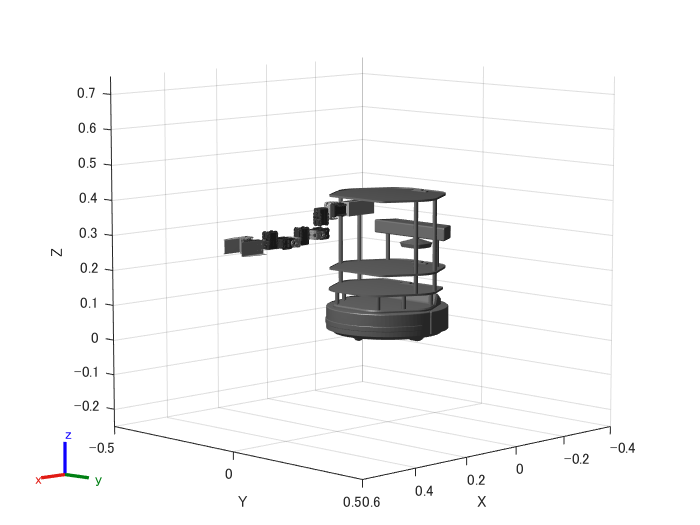

x0 = 0.5084

y0 = -0.0300

z0 = 0.2976

if use_plot
    show(robot, q, Frames="off");
    xlim([-0.4 0.6])
    ylim([-0.5 0.5])
    zlim([-0.25 0.75])
end

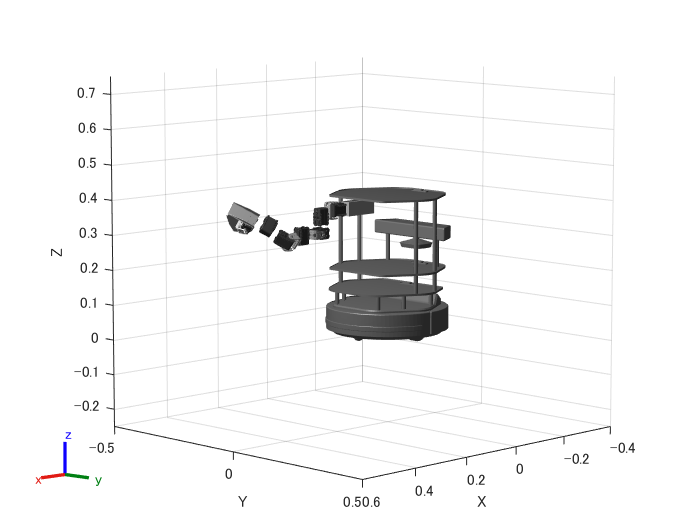

% q(1) -> y+
q(1).JointPosition = deg2rad(0);
% q(2) -> 正面から見て反時計回り
q(2).JointPosition = deg2rad(0);
% q(3) -> z+
q(3).JointPosition = deg2rad(0);
% q(4) -> 正面から見て反時計回り  実機でも同じ
q(4).JointPosition = deg2rad(50);
% q(5) -> z+
q(5).JointPosition = deg2rad(50);
% q(6) -> 正面から見て反時計回り  実機でも同じ
q(6).JointPosition = deg2rad(-30);
% q(7) -> +で開く -50～-60くらいで閉じる
q(7).JointPosition = deg2rad(-50);
if use_plot
    show(robot, q, Frames="off");
    xlim([-0.4 0.6])
    ylim([-0.5 0.5])
    zlim([-0.25 0.75])
end


qs = ["0" "0" "0" "0" "0" "0" "0"];
for j = 1:7
    % radをdegにし、±150度を0～1023にする
    qs(j) = num2str(rad2deg(q(j).JointPosition) * reverse(j) / 300 * 1023 + 500);
end
clib.webcface.wcfFuncRunS(wcli, target, "move_servo", qs)

ans = ""

 
clib.webcface.wcfClose(wcli);